#  Quadruped robot MBRL training tasks

Test for model based RL in MATLAB

Retrived from: [https://www.mathworks.com/help/reinforcement-learning/ug/model-based-reinforcement-learning-using-custom-training-loop.html](https://www.mathworks.com/help/reinforcement-learning/ug/model-based-reinforcement-learning-using-custom-training-loop.html)

## Create Environment

clear
clc
seedNum = 36;
rng(seedNum)
% load("modelParams.mat")
vali = 1;
if vali == 0
    mdl = 'RLtrot';
    isUsePretrainedAgent = 0;
    isUseExtAct = 0;
    SaveAgentReward = 150;
    StopTrainReward = 250;
    DiscountFactor = 0.96;
    criticLearnRate = 2e-3; %2
    actorLearnRate = 1e-3; %1 
elseif vali == 1
    isUsePretrainedAgent = 1;
    isUseExtAct = 1;
    mdl = 'RLvali_2021b';
    SaveAgentReward = 30;
    StopTrainReward = 60;
    DiscountFactor = 0.96;
    criticLearnRate = 2e-3; %2
    actorLearnRate = 10e-4; %1
else
    isUsePretrainedAgent = 0;
    mdl = 'RLvali_2021b';
    SaveAgentReward = 100;
    StopTrainReward = 120;
    DiscountFactor = 0.98;
    criticLearnRate = 1e-3; %2
    actorLearnRate = 5e-4; %1
%     isResume = 1;
%     preTrainingStats = ;
end
% robot animation on/off
set_param(mdl,'SimMechanicsOpenEditorOnUpdate','on','FastRestart','on') 

numAct = 4;
% Obs include: #rot x,y,z #v x,y,z #fn: FR,FL,RL,RR
numObs = 10 + numAct;

% Normalization
load("norm_para_all.mat")
state_init = [0	0 0	0 0 0 0.5 0.5 0.5 0.5];
x_norm_init=(state_init - y_norm_min)./y_norm_range;

% Robot settings
alpha_r_gain = 0;
alpha_b_gain = pi/5;
z_l_gain = 8e-3;

% Robot runtime
Tf = 5;
Ts = 0.05;

% added in amplitude 1
rotVariance = 0.002; % 0.001
fnVariance = 0.005; % 0.002
speedVariance = 0.002; % 0.001

## Training settings

#### Target speed

VRef = 0.3; % reference velocity

#### Actor-Critic learning settings

TargetSmoothFactor = 1e-3;

ExperienceBufferLength = 16384; % 2^14
MiniBatchSize = 4096; %2^12

EntropyWeight = 1;
EntropyLearnRate = 1e-4;
TargetEntropy = -numAct*1;

maxEpisodes = 400;

maxSteps = floor(Tf/Ts);

% !!! For continued/curriculum training -->
% !!!Change dir to run1,2,3 to avoid overlapping saved agents
SaveAgentDir = pwd+"\savedAgents";

if ~exist(SaveAgentDir, 'dir')
    mkdir(SaveAgentDir)
end

UseParallel = false;
numsWorkers = 3;

#### Overall training settings

doTraining = 1; % if not train, noise is disabled

startAgentTime = 32*Ts;
isCheckDone = 1;
isContactBoolean = 1;

% !!! for continued training -->
% !!! Change the value to 1 and update the latest agent!
if isUsePretrainedAgent == 0
    fprintf('Training ready');
else
    pretrainedAgent = SaveAgentDir + "\Agent233.mat";
end
% !!! for curriculum training -->
% !!! for now (1224), use agent : 
%  "savedAgents\Agent035ForCurriculum\agent035.mat"

## Create environment info

actInfo = rlNumericSpec([numAct 1],'LowerLimit',0,'UpperLimit', 1);
actInfo.Name = 'actions';

obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = 'observations';

blk = [mdl, '/RL Agent'];
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo,'UseFastRestart','on');


Create storage for entropy record and episode number

% EpiCount = 0;
% instantTrainingStats = [];
entropyListSize = maxSteps*maxEpisodes;
EntropyList = zeros(entropyListSize, 1);
EntropyList(1)=TargetEntropy;

EntropyWeightList = zeros(entropyListSize, 1);
EntropyWeightList(1)=EntropyWeight;

## Specify agent training options (parallel training try)

maxSteps = floor(Tf/Ts);  

trainOpts = rlTrainingOptions(...
    'UseParallel',UseParallel,...
    'MaxEpisodes',maxEpisodes,...
    'MaxStepsPerEpisode',maxSteps,...
    'ScoreAveragingWindowLength',10,...
    'Verbose',true,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',StopTrainReward,...                   
    'SaveAgentCriteria','EpisodeReward',... 
    'SaveAgentValue',SaveAgentReward,...
    'SaveAgentDirectory', SaveAgentDir);

if trainOpts.UseParallel == true
    delete(gcp('nocreate'));
    parpool(numsWorkers); % specify the number of workers
    %set_param(mdl,'SimMechanicsOpenEditorOnUpdate','off')
    trainOpts.ParallelizationOptions.Mode = 'async';
    trainOpts.ParallelizationOptions.StepsUntilDataIsSent = -1;
    trainOpts.ParallelizationOptions.DataToSendFromWorkers = 'Experiences';
end

## Critic Construction

if isUsePretrainedAgent
    load(pretrainedAgent)
    if exist('saved_agent','var')
        agent = saved_agent;
    end
else
    createAgent
end

## Train or test agent

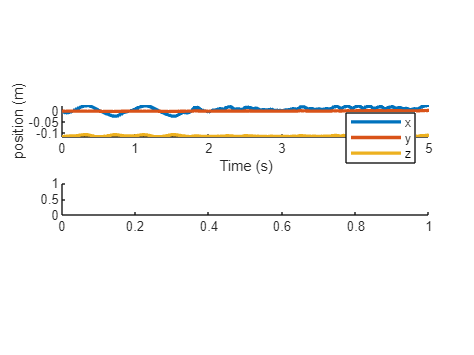

Dot indexing is not supported for variables of this type.

if doTraining
    save_system(mdl)
    trainingStats = train(agent,env,trainOpts);
    
    % !!! RUN the following lines to save current agent and workspace!
    currentTimestr = datestr(now,'yyyy_mmmm_dd_HH_MM');
    save(append(SaveAgentDir,'\agent_', currentTimestr,'.mat'),'agent','trainingStats');
    save(append(SaveAgentDir,'\workspace_seedNum',num2str(seedNum),'_', currentTimestr,'.mat'));
    %---------------------%
else
    rotVariance = 0;
    fnVariance = 0;
    speedVariance = 0;
    agent.AgentOptions.UseDeterministicExploitation = 1;

%     randObs = {rand(obsInfo(1).Dimension)};
%     DistributionParams = evaluate(agent.Actor, randObs);
%     DistributionParams = DistributionParams{1};
% 
%     figure('Name','Current agent info. with a randObs','NumberTitle','off')
%     set(gcf,'Visible','on')
%     subplot(3,1,1)
%     plot(DistributionParams(1:4),'LineWidth',2)
%     xticks(1:1:4)
%     xlabel('Action number')
%     ylabel('Action distribution mean')
%     hold off
%     
%     subplot(3,1,2)
%     plot(DistributionParams(5:8),'LineWidth',2)
%     xticks(1:1:4)
%     xlabel('Action number')
%     ylabel('Action distribution std')
%     hold off

%     subplot(3,1,3)
%     for i = 1:1:50
%         actionOut = getAction(agent,randObs);
%         plot(actionOut{1},'LineWidth',1)
%         hold on
%     end
%     xticks(1:1:4)
%     xlabel('Action number')
%     ylabel('Action for a randObs')
%     hold off

    tic
    simout = sim('RLvali_2021b.slx');
    toc

    figure('Name','Robot body information','NumberTitle','off')
    set(gcf,'Visible','on')
    subplot(4,1,1)
    plot(simout.COT.Time, simout.COT.Data,'LineWidth',2)
    xlabel('Time (s)')
    ylabel('Reward')
    hold off
    
    subplot(4,1,2)
    hold on
    plot(simout.FLfootTrace.Time, simout.FLfootTrace.Data(:,1),'LineWidth',2)
    plot(simout.FLfootTrace.Time, simout.FLfootTrace.Data(:,2),'LineWidth',2)
    plot(simout.FLfootTrace.Time, simout.FLfootTrace.Data(:,3),'LineWidth',2)
    legend('x','y','z')
    xlabel('Time (s)')
    ylabel('position (m)')
    hold off
    
    subplot(4,1,3)
    hold on
    plot(simout.Observations.vx.Time, simout.Observations.vx.Data,'LineWidth',2)
    plot(simout.Observations.vy.Time, simout.Observations.vy.Data,'LineWidth',2)
    plot(simout.Observations.vz.Time, simout.Observations.vz.Data,'LineWidth',2)
    legend('vx','vy','vz')
    xlabel('Time (s)')
    ylabel('Speed (m/s)')
    hold off
    
    subplot(4,1,4)
    
    rotData = reshape(simout.Observations.rot.Data,size(simout.Observations.rot.Data,[1,3]));
    hold on
    plot(simout.Observations.rot.Time, rotData(1,:),'LineWidth',2)
    plot(simout.Observations.rot.Time, rotData(2,:),'LineWidth',2)
    plot(simout.Observations.rot.Time, rotData(3,:),'LineWidth',2)
    legend('rotX','rotY','rotZ')
    xlabel('Time (s)')
    ylabel('Rotate (rad)')
    hold off
    
    figure('Name','Robot leg information','NumberTitle','off')

    windowSize = 1; 
    b = (1/windowSize)*ones(1,windowSize);
    a = 1;

    set(gcf,'Visible','on')
    subplot(4,1,1)
    hold on
    plot(simout.Observations.SigsFromLegs.FnFR.Time,simout.Observations.SigsFromLegs.FnFR.Data,'LineWidth',2)
    plot(simout.Observations.SigsFromLegs.FnFL.Time,simout.Observations.SigsFromLegs.FnFL.Data,'LineWidth',2)
    plot(simout.Observations.SigsFromLegs.FnRR.Time,simout.Observations.SigsFromLegs.FnRR.Data,'LineWidth',2)
    plot(simout.Observations.SigsFromLegs.FnRL.Time,simout.Observations.SigsFromLegs.FnRL.Data,'LineWidth',2)
    legend('FnFR','FnFL','FnRR','FnRL')
    xlabel('Time (s)')
    ylabel('Contact force (N)')
    hold off
    
    subplot(4,1,2)
    hold on
    bendFRData = reshape(simout.Observations.SigsFromLegs.bendFR.Data,size(simout.Observations.SigsFromLegs.bendFR.Data,[1,3]));
    plot(simout.Observations.SigsFromLegs.bendFR.Time,filter(b,a,bendFRData(2,:)),'LineWidth',2)
    bendFLData = reshape(simout.Observations.SigsFromLegs.bendFL.Data,size(simout.Observations.SigsFromLegs.bendFL.Data,[1,3]));
    plot(simout.Observations.SigsFromLegs.bendFL.Time,filter(b,a,bendFLData(2,:)),'LineWidth',2)
    bendRRData = reshape(simout.Observations.SigsFromLegs.bendRR.Data,size(simout.Observations.SigsFromLegs.bendRR.Data,[1,3]));
    plot(simout.Observations.SigsFromLegs.bendRR.Time,filter(b,a,bendRRData(2,:)),'LineWidth',2)
    bendRLData = reshape(simout.Observations.SigsFromLegs.bendRL.Data,size(simout.Observations.SigsFromLegs.bendRL.Data,[1,3]));
    plot(simout.Observations.SigsFromLegs.bendRL.Time,filter(b,a,bendRLData(2,:)),'LineWidth',2)
    legend('bendFR','bendFL','bendRR','bendRL')
    xlabel('Time (s)')
    ylabel('Bending angle (rad)')
    hold off
    
    subplot(4,2,5)
    hold on
    plotStartStep = 1; %find(simout.FLfootTrace.Time > (startAgentTime-0.9), 1);
    plotEndStep = size(simout.FLfootTrace.Time,1); % find(simout.FLfootTrace.Time > (startAgentTime-0.1), 1);
    plot(simout.FLfootTrace.Data(plotStartStep:plotEndStep,1),simout.FLfootTrace.Data(plotStartStep:plotEndStep,3),'LineWidth',2)
    legend('FL foot trace')
    xlabel('x (m)')
    ylabel('z (m)')
    hold off

    subplot(4,2,6)
    hold on
    plot(simout.FRfootTrace.Data(plotStartStep:plotEndStep,1),simout.FRfootTrace.Data(plotStartStep:plotEndStep,3),'LineWidth',2)
    legend('FR foot trace')
    xlabel('x (m)')
    ylabel('z (m)')
    hold off

    subplot(4,2,7)
    hold on
    plot(simout.RLfootTrace.Data(plotStartStep:plotEndStep,1),simout.RLfootTrace.Data(plotStartStep:plotEndStep,3),'LineWidth',2)
    legend('RL foot trace')
    xlabel('x (m)')
    ylabel('z (m)')
    hold off

    subplot(4,2,8)
    hold on
    plot(simout.RRfootTrace.Data(plotStartStep:plotEndStep,1),simout.RRfootTrace.Data(plotStartStep:plotEndStep,3),'LineWidth',2)
    legend('RR foot trace')
    xlabel('x (m)')
    ylabel('z (m)')
    hold off

end